hours_per_day = 12

hours_per_day = 12

base_power_generation_per_hour = 300; %unit: watt-hours
hours_of_sunlight_per_day = hours_per_day;
sunlight_angles = 0:(pi/(hours_per_day*60)):pi; %resolution: minute
time = 0:(1/(60)):hours_per_day; %resolution: minute
%watt generation of a tracking solar panel over a hours_per_day hour day
tracking_base_power_generation = base_power_generation_per_hour + zeros( 1, 721 );
%watt generation of a non-tracking solar panel over a hours_per_day hour day
none_tracking_base_power_generation = base_power_generation_per_hour*sin(pi*time/hours_per_day);
%Derived from integral of tracking_base_power_generation
cumulative_generation_tracking = time*base_power_generation_per_hour

cumulative_generation_tracking = 1.0e+03 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


%Derived from integral of none_tracking_base_power_generation
cumulative_generation_no_tracking = -base_power_generation_per_hour*cos(pi*time/hours_per_day)*(hours_per_day/pi) + base_power_generation_per_hour*(hours_per_day/pi)

cumulative_generation_no_tracking = 1.0e+03 *

         0    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0021    0.0025    0.0028    0.0032    0.0035    0.0039    0.0044    0.0048    0.0053    0.0058    0.0063    0.0068    0.0074    0.0079    0.0085    0.0092    0.0098    0.0105    0.0112    0.0119    0.0126    0.0133    0.0141    0.0149    0.0157    0.0166    0.0174    0.0183    0.0192    0.0201    0.0211    0.0220    0.0230    0.0240    0.0250    0.0261


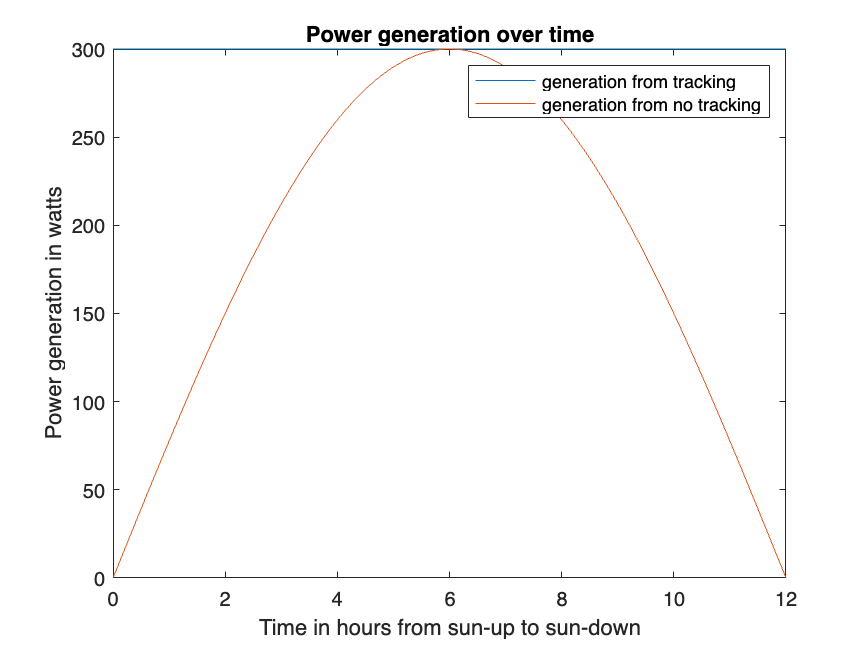

plot(time, tracking_base_power_generation)
hold on
plot(time, none_tracking_base_power_generation)
title("Power generation over time")
ylabel("Power generation in watts")
xlabel("Time in hours from sun-up to sun-down")
legend("generation from tracking", "generation from no tracking")

hold off


plot(time, cumulative_generation_tracking)
hold on
plot(time, cumulative_generation_no_tracking)
title("Cumulative power generation over time")
ylabel("Cumulative generation in watt-hours")
xlabel("Time in hours from sun-up to sun-down")
legend("cumulative generation tracking", "cumulative generation no tracking")
percentage_generation_difference = (1-cumulative_generation_no_tracking/cumulative_generation_tracking)*100

percentage_generation_difference = 32.9098

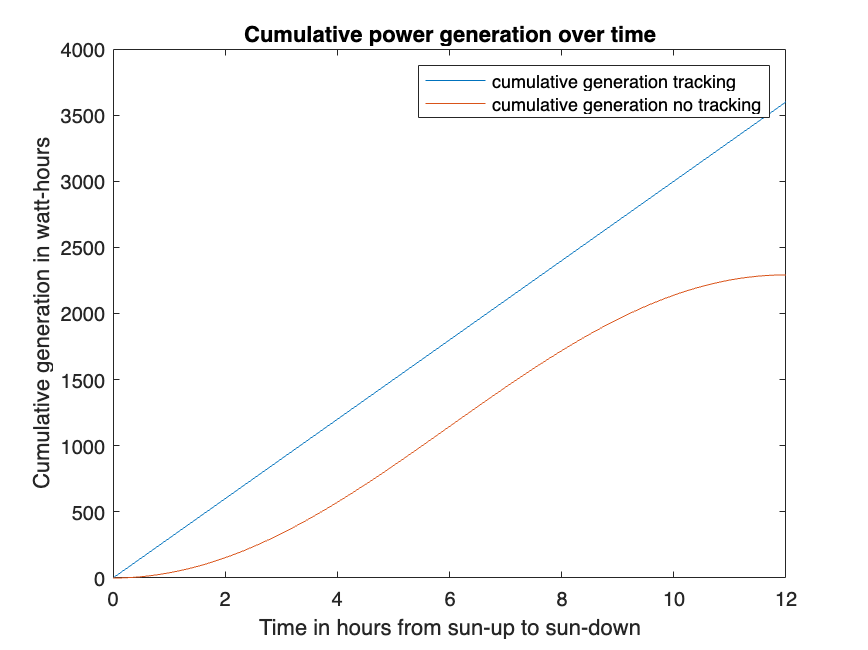

hold off

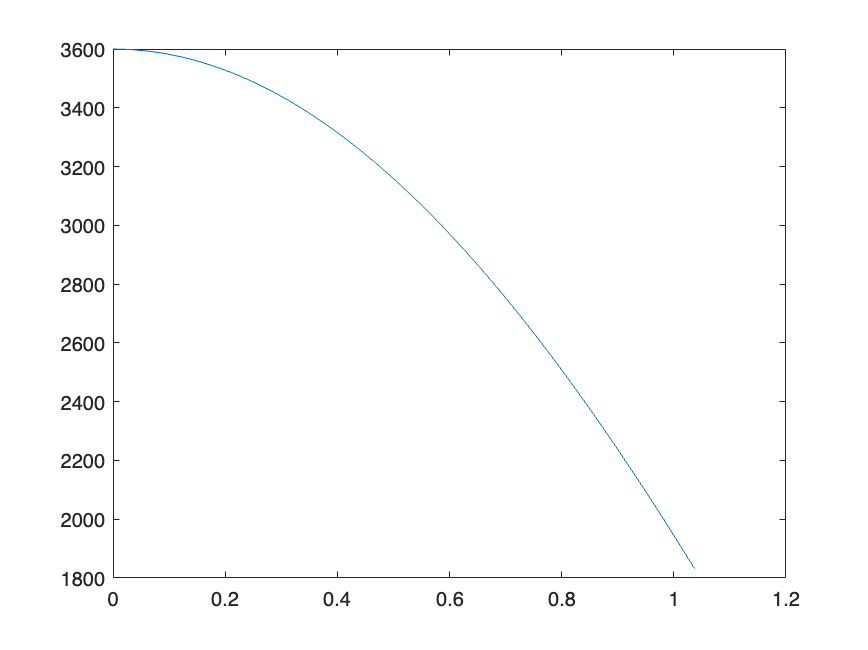

%what if the tracking is on average offset by a constant amount
theta_offsets = 0:pi/100:pi/3;
offset_total_power_generation = base_power_generation_per_hour*12*sin(theta_offsets+pi/2);
plot(theta_offsets, offset_total_power_generation);